# Lab4

# MirHamed Jafarzadeh - 810195374

# Sajjad Pakdaman Savoji - 810195517

## *Part 4 - 1:*

    1. Bit Generating

pkt_size = 10;
M = 4;
k = log2(M);
b_tx = bit_gen(pkt_size, k)

b_tx =      0     0
     1     1
     0     1
     1     1
     1     0
     1     0
     0     0
     0     1
     0     0
     1     1


    2. Bit-to-Symbol Mapping

b_gray = gray_code(k)

b_gray =      0     0
     0     1
     1     1
     1     0


sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1) & b_tx(:,2) == b_gray(i,2);
    sym_idx(indx) = i;
end
sym_idx

sym_idx =      1     3     2     3     4     4     1     2     1     3


[pam_cons, Es_avg] = constellation(M,'pam');
mod_sym = pam_cons(sym_idx)

mod_sym =    -1.3416    0.4472   -0.4472    0.4472    1.3416    1.3416   -1.3416   -0.4472   -1.3416    0.4472


 3. Transmitting Pulse Shaping

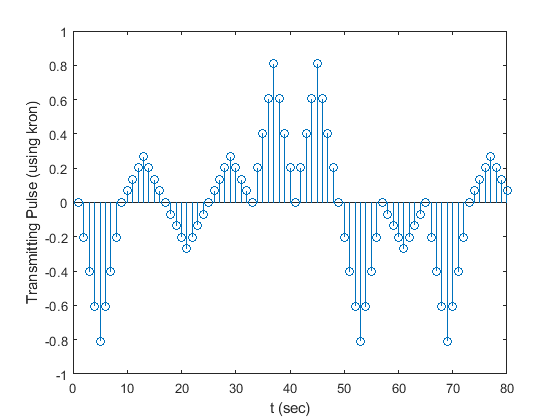

smpl_per_symbl = 8;
fs = 10; % for testing
[tx_out1, cnstl1] = pulse_modulation(sym_idx, 'pam', M, fs, smpl_per_symbl, 'triangular', 'kron', 0);
[tx_out2, cnstl2] = pulse_modulation(sym_idx, 'pam', M, fs, smpl_per_symbl, 'triangular', 'conv', 0);
stem(tx_out1)
ylabel('Transmitting Pulse (using kron)');
xlabel('t (sec)');

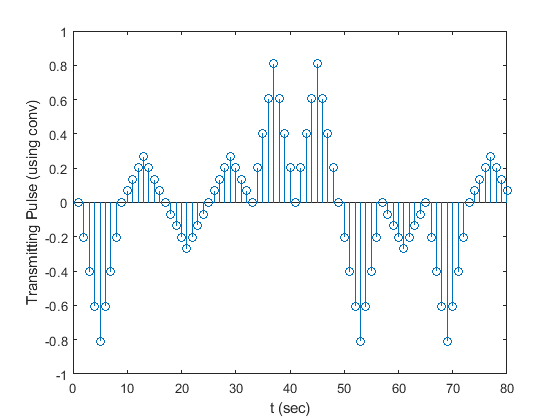

stem(tx_out2)
ylabel('Transmitting Pulse (using conv)');
xlabel('t (sec)');

## *Part 4 - 2:*

    1. Power Recognizing of Receiving Signals along with Basic Signals

[p, ~] = pulse_shape('triangular', fs, smpl_per_symbl, 0);
rec_sym1 = corr_match(tx_out1, p, smpl_per_symbl, 'correlator')

rec_sym1 =    -1.3416    0.4472   -0.4472    0.4472    1.3416    1.3416   -1.3416   -0.4472   -1.3416    0.4472


rec_sym2 = corr_match(tx_out1, p, smpl_per_symbl, 'matched_filter')

rec_sym2 =    -1.3416    0.4472   -0.4472    0.4472    1.3416    1.3416   -1.3416   -0.4472   -1.3416    0.4472


    2. Minimum Distance Detector

det_sym = min_dist_detector(rec_sym1, cnstl1)

det_sym =    -1.3416    0.4472   -0.4472    0.4472    1.3416    1.3416   -1.3416   -0.4472   -1.3416    0.4472


    3. Pulse Demodulation

rx_signal = tx_out1;
[det_sym_idx, rec_sym_tot] = pulse_demodulation(rx_signal, 'pam', M, fs, smpl_per_symbl, 'triangular', 'correlator', 0)

det_sym_idx =      1     3     2     3     4     4     1     2     1     3


rec_sym_tot =    -1.3416    0.4472   -0.4472    0.4472    1.3416    1.3416   -1.3416   -0.4472   -1.3416    0.4472


det_sym_idx == sym_idx

ans = 1×10 logical array
   1   1   1   1   1   1   1   1   1   1
